1 Применение фильтра с конечной импульсной характеристикой

1.1 Инициализация и формирование значений основных параметров

clear all; % Очистка памяти
close all; % Закрытие всех окон с графиками
clc; % Очистка окна команд и сообщений
fontSize = 10; % Размер шрифта графиков
tColor = 'b'; % Цвет графиков во временной области
fColor = [1 0.4 0]; % Цвет графиков в частотной области
fd = 16000; % Частота дискретизации, Гц
dt = 1; % Длительность исходного сигнала, с
N = 16000; % Количество отсчётов исходного сигнала

1.2 Моделирование белого шума в качестве исходного сигнала

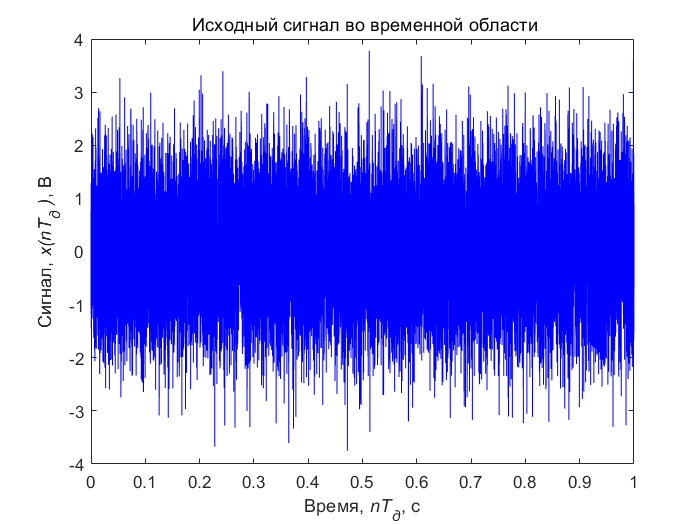

t = linspace(0,dt,N); % Формирование области определения во временной области
noise = wgn(1,N,0); % Массив отсчётов белого шума - исходного сигнала
figure; plot(t, noise, 'Color', tColor);
set(get(gcf, 'CurrentAxes'), 'FontSize', fontSize); % Изменение шрифта
title('\rm Исходный сигнал во временной области'); % Заголовок
xlabel('Время,\it nT_д\rm, с'); % Надпись оси абсцисс
ylabel('Сигнал,\it x(nT_д )\rm, В'); % Надпись оси ординат

1.3 Построение амплитудного спектра белого шума

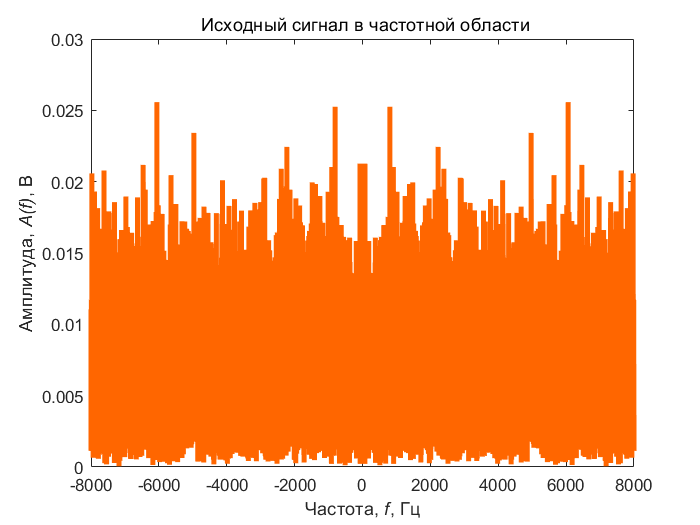

f = linspace(0, fd, N); % Формирование области определения в частотной области
% Массив отсчётов спектра исходного сигнала
fnoise = abs(fft(noise)/N);
figure; plot([-fliplr(f(1:end/2)) f(1:end/2)], fftshift(fnoise),...
    'Color', fColor, 'LineWidth', 3);
%axis([-fd/2 fd/2 0 volume*0.6]); % Диапазон значений осей
set(get(gcf, 'CurrentAxes'), 'FontSize', fontSize); % Изменение шрифта
title('\rm Исходный сигнал в частотной области'); % Заголовок
xlabel('Частота,\it f\rm, Гц'); % Надпись оси абсцисс
ylabel('Амплитуда,\it A(f)\rm, В'); % Надпись оси ординат

1.4 Создание режекторного фильтра в Matlab Filter Designer

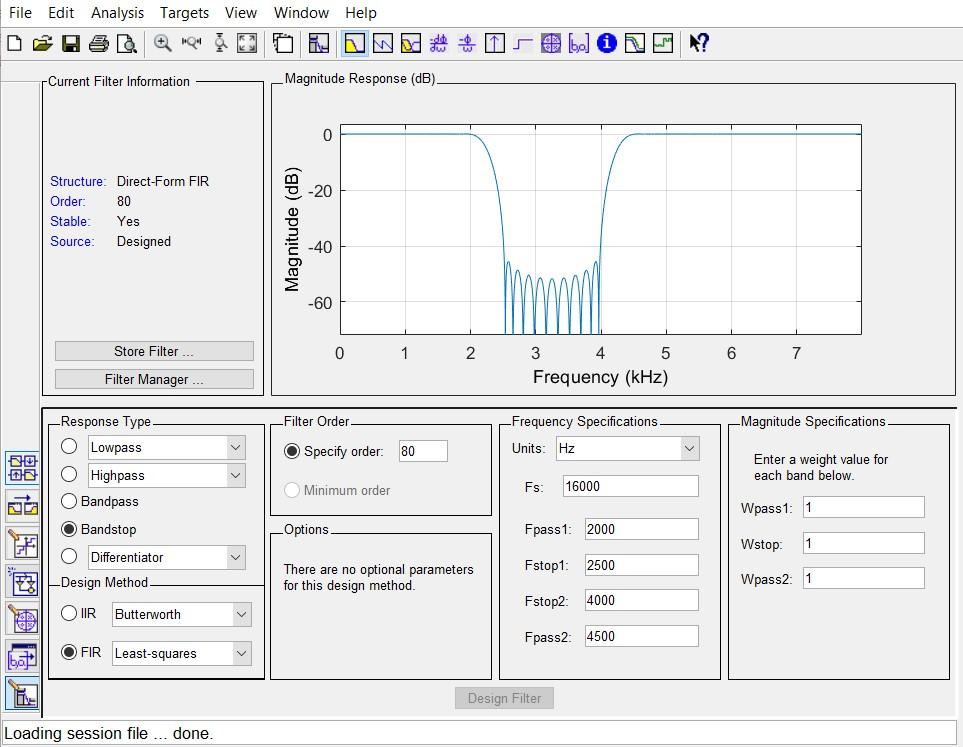

1.5 Экспорт коэффициентов фильтра в файл

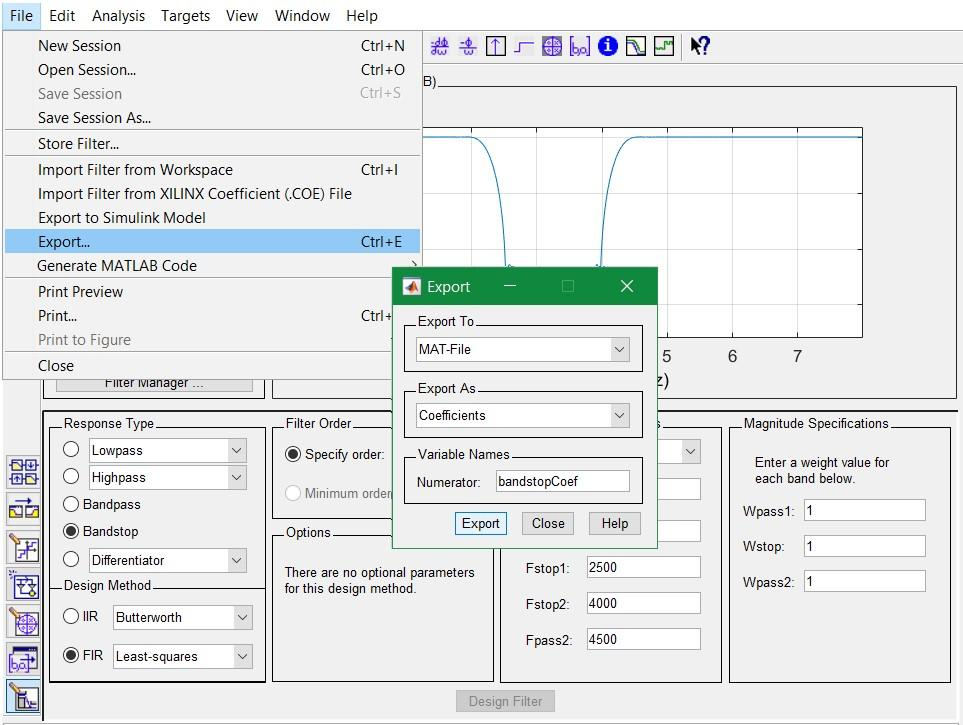

1.6 Фильтрация белого шума

load('bandstopFilter.mat'); % Загрузка файла с коэффициентами фильтра
global bandstopCoef; % Массив коэффициентов КИХ-фильтра

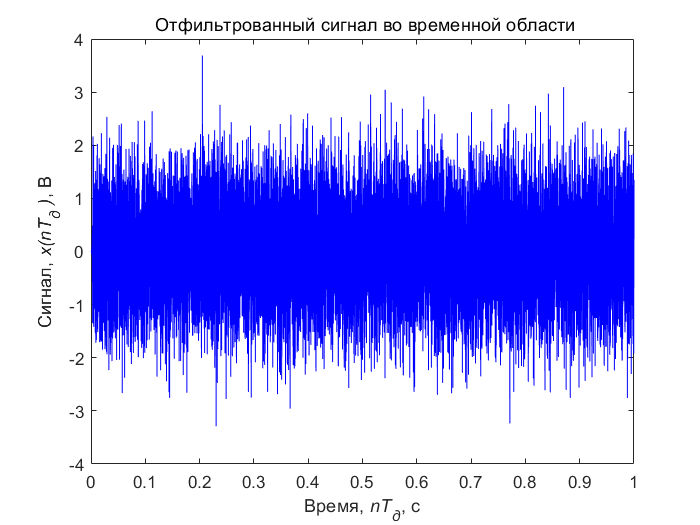

data = filter(bandstopCoef, 1, noise); % Применение фильтра к белому шуму
figure; plot(t, data, 'Color', tColor);
set(get(gcf, 'CurrentAxes'), 'FontSize', fontSize); % Изменение шрифта
title('\rm Отфильтрованный сигнал во временной области'); % Заголовок
xlabel('Время,\it nT_д\rm, с'); % Надпись оси абсцисс
ylabel('Сигнал,\it x(nT_д )\rm, В'); % Надпись оси ординат

1.7 Построение амплитудного спектра отфильтрованного сигнала

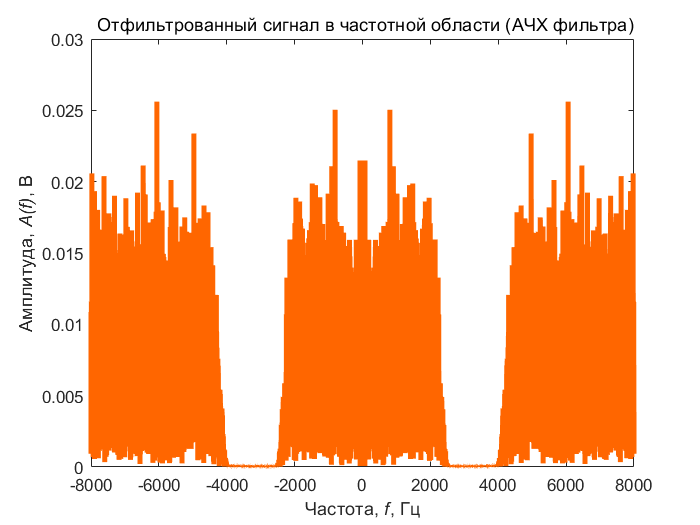

% Массив отсчётов спектра отфильтрованного сигнала
fdata = abs(fft(data)/N);
figure; plot([-fliplr(f(1:end/2)) f(1:end/2)], fftshift(fdata),...
    'Color', fColor, 'LineWidth', 3);
%axis([-fd/2 fd/2 0 volume*0.6]); % Диапазон значений осей
set(get(gcf, 'CurrentAxes'), 'FontSize', fontSize); % Изменение шрифта
title('\rm Отфильтрованный сигнал в частотной области (АЧХ фильтра)'); % Заголовок
xlabel('Частота,\it f\rm, Гц'); % Надпись оси абсцисс
ylabel('Амплитуда,\it A(f)\rm, В'); % Надпись оси ординат